time = val.time;
numbers = val.numbers;
enter = val.enter;
leave = val.leave;

e = enter / 30;
l = leave / 30;

t_wait = 1:18000;

%initializing the t_wait
interval = 12

interval = 12


for i=1:18000
    t_wait(1:i)=0;
end


%the main code
for i=1:18000
    temp = 0;
    for j=1:18000
        if  temp >= numbers(i,1)
            t_wait(i) = j;
            break
        else 
            temp = temp + l(j * interval + i,1);
        end
    end
end


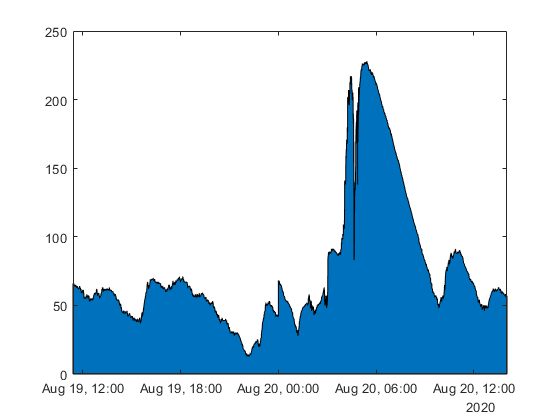

time_temp = time(1:18000).';
area(time_temp,t_wait,'DisplayName','t_wait')
xlim([time_temp(1,1)  time_temp(1,18000)])

area(time,l,'DisplayName','l')

xlim([time_temp(1,1)  time(20282)])

area(time,numbers,'DisplayName','numbers')

xlim([time_temp(1,1)  time(20282)])